Throughput traces - INDIS 2023 datasets

   Nagi Rao

   raons@ornl.gov

   started: August 12, 2022

   modified: August 12, 2022, July 21, 2023; September 26, 2023

**Reference**:

Nageswara S. V. Rao. 2023. Experimental Study of TCP Throughput Profiles and Dynamics Over Dedicated Connections. In Workshops of The International Conference on High Performance Computing, Network, Storage, and Analysis (SC-W 2023), November 12–17, 2023, Denver, CO, USA. ACM, New York, NY, USA, 8 pages. https://doi.org/10.1145/3624062.3624589

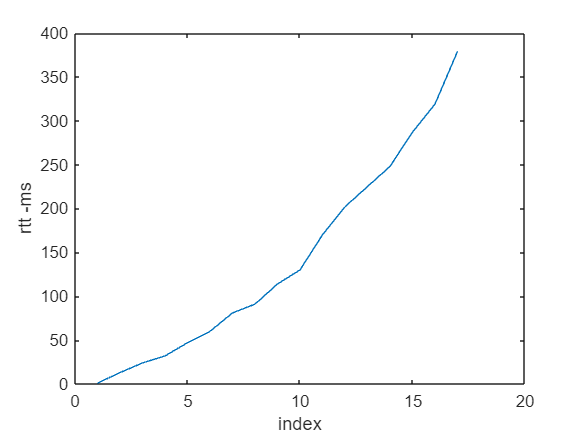

addpath('C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\matlab_dir');

n_measure=10;

rtt=[ 1 12 22 29 49 75 93 105 150 183 366 ]; % 0 is 1
num_rtt=length(rtt);
rtt_g=[ 1 13 24 32 47 60 81 91 114 130 170 202 225 248 287 319 376 ]; % 0 is 1
num_rtt_g=length(rtt_g);

rtt_hybla=[ 1 13];

testbed_rtt=[ 0 12 22 29 49 75 93 105 150 183 366 ];
num_testbed_rtt=length(testbed_rtt);
testbed_rtt_g=[ 1 13 24 32 47 60 81 91 114 130 170 202 225 248 287 318 376 ];
num_testbed_rtt_g=length(rtt_g);

date_set=[ '0 ms  '; '11 ms '; '22 ms '; '29 ms '; '49 ms '; '75 ms '; '93 ms ';  '105 ms'; '150 ms'; '183 ms'; '366 ms'] ;
celldate = cellstr(date_set);

date_set1=[ '0  '; '11 '; '22 '; '29 '; '49 '; '75 '; '93 ';  '105'; '150'; '183'; '366'] ;
celldate1 = cellstr(date_set1);

date_set_g=[ '0 ms  '; '13 ms '; '24 ms '; '32 ms '; '47 ms '; '60 ms '; '81 ms '; '91 ms '; ...
    '114 ms'; '130 ms'; '170 ms'; '202 ms'; '225 ms'; '248 ms'; '287 ms'; '319 ms'; '376 ms'] ;
celldate_g = cellstr(date_set_g);

date_set_g1=[ '0  '; '13 '; '24 '; '32 '; '47 '; '60 '; '81 '; '91 '; ...
    '114'; '130'; '170'; '202'; '225'; '248'; '287'; '319'; '376'] ;
celldate_g1 = cellstr(date_set_g1);

tau(1)=1;
tau(2)=13;
tau(3)=24;
tau(4)=32;
tau(5)=47;
tau(6)=60;
tau(7)=81;
tau(8)=91;
tau(9)=114;
tau(10)=130;
tau(11)=170;
tau(12)=202;
tau(13)=225;
tau(14)=248;
tau(15)=287;
tau(16)=319;
tau(17)=379;
n_tau=17;

figure(10); clf reset
plot(tau); hold on
xlabel('index');
ylabel('rtt -ms');


dir_name='C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\traces'

dir_name = 'C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\traces'

### BBR Traces

Polatis-ixia: no loss

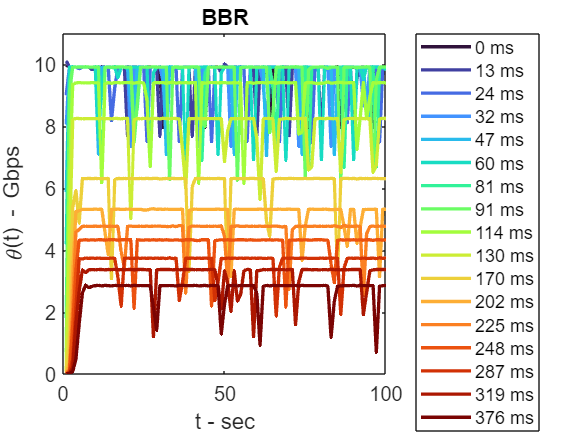

cc_turbo=turbo(num_rtt_g);
start_cc=5;
file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-bbr-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_polatis_2f_time,testbed_bbr_polatis_2f_trace]=read_tracex_testbed_txt('bbr','1',rtt_g,testbed_dir_name_g);

figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_bbr_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('BBR');
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

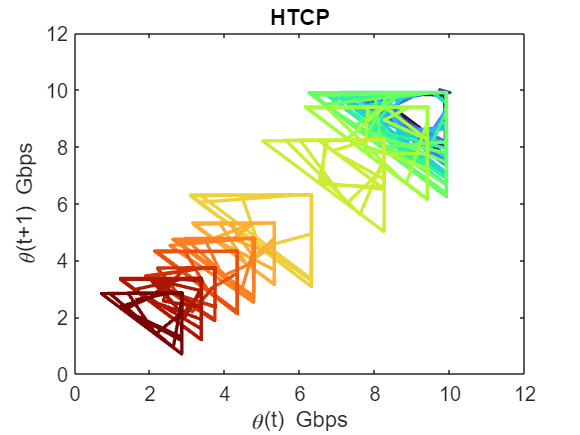


figure(211); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_bbr_polatis_2f_trace(i,j+1);
    end
    plot(testbed_bbr_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('HTCP');
xlim([0 12]);
ylim([0 12]);
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)

### CUBIC Polatis

Polatis-ixia: no loss

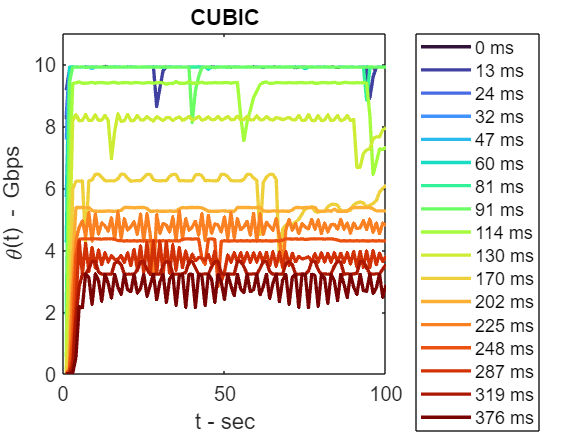

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-cubic-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_polatis_2f_time,testbed_cubic_polatis_2f_trace]=read_tracex_testbed_txt('cubic','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_cubic_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('CUBIC')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

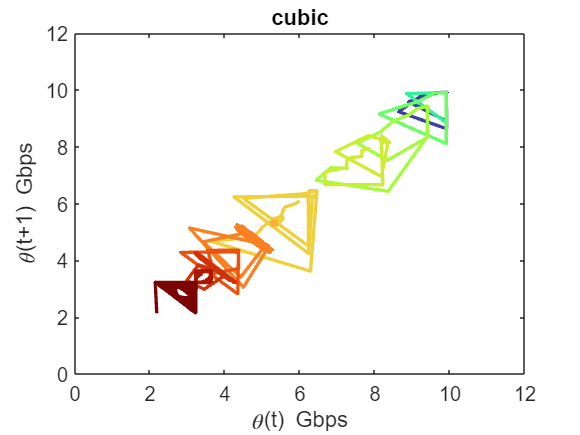


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_cubic_polatis_2f_trace(i,j+1);
    end
    plot(testbed_cubic_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('cubic');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

### Highspeed Polatis

Polatis-ixia: no loss

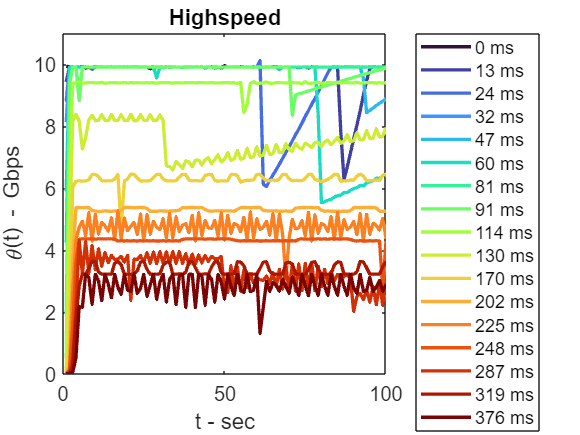

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-highspeed-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_highspeed_polatis_2f_time,testbed_highspeed_polatis_2f_trace]=read_tracex_testbed_txt('highspeed','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_highspeed_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('Highspeed')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

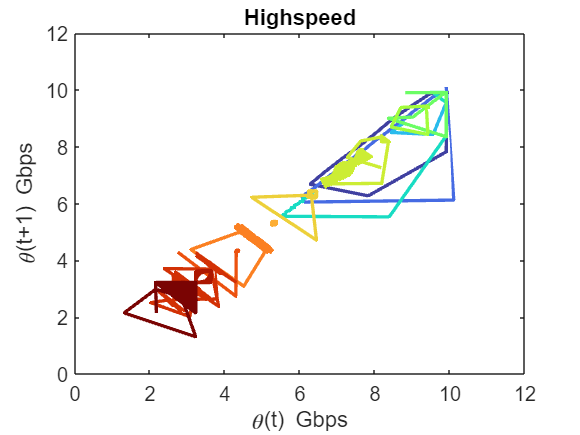


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_highspeed_polatis_2f_trace(i,j+1);
    end
    plot(testbed_highspeed_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('Highspeed');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

### HTCP Polatis

Polatis-ixia: no loss

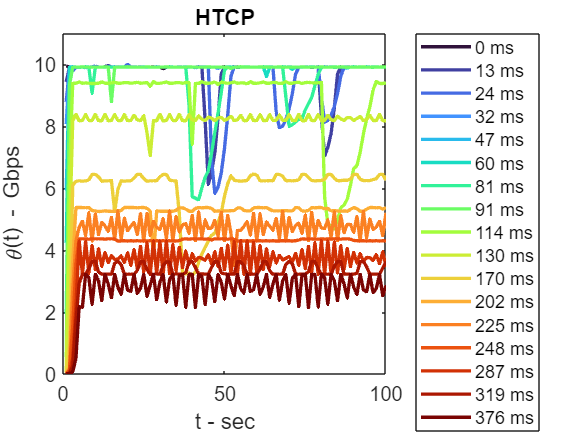

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-htcp-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_polatis_2f_time,testbed_htcp_polatis_2f_trace]=read_tracex_testbed_txt('htcp','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_htcp_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('HTCP')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

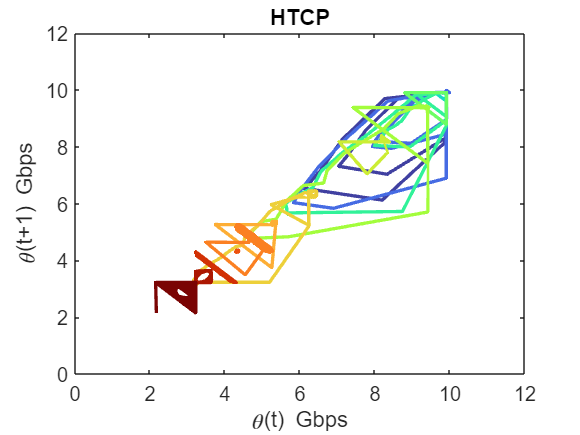


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_htcp_polatis_2f_trace(i,j+1);
    end
    plot(testbed_htcp_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('HTCP');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

### Illinois Polatis

Polatis-ixia: no loss

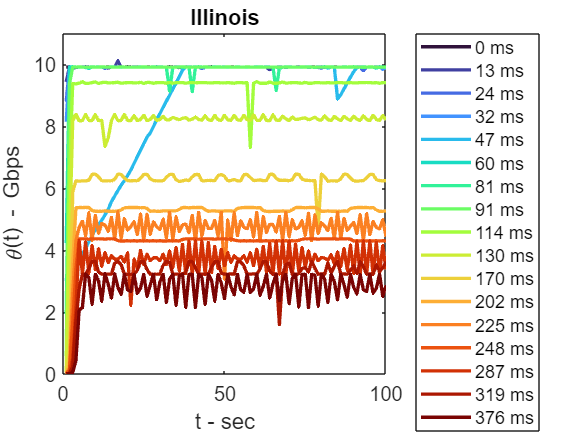

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-illinois-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_illinois_polatis_2f_time,testbed_illinois_polatis_2f_trace]=read_tracex_testbed_txt('illinois','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_illinois_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('Illinois')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

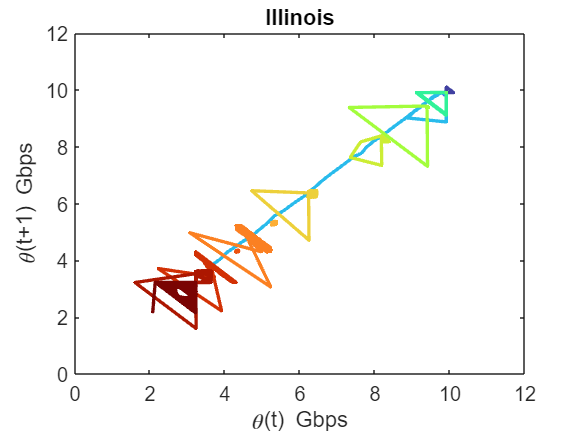


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_illinois_polatis_2f_trace(i,j+1);
    end
    plot(testbed_illinois_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('Illinois');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

### LP Polatis

Polatis-ixia: no loss

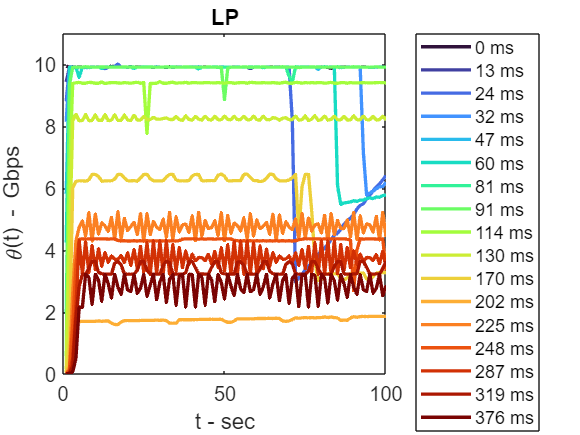

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-lp-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_lp_2f_time,testbed_lp_2f_trace]=read_tracex_testbed_txt('lp','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_lp_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('LP')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

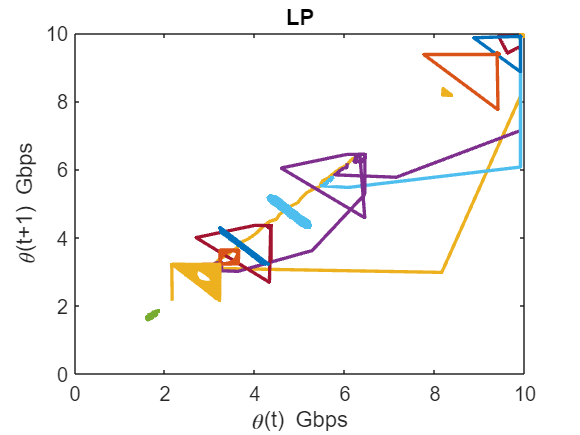


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_lp_2f_trace(i,j+1);
    end
    plot(testbed_lp_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2); hold on
end
title('LP');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)

### Scalable Polatis

Polatis-ixia: no loss

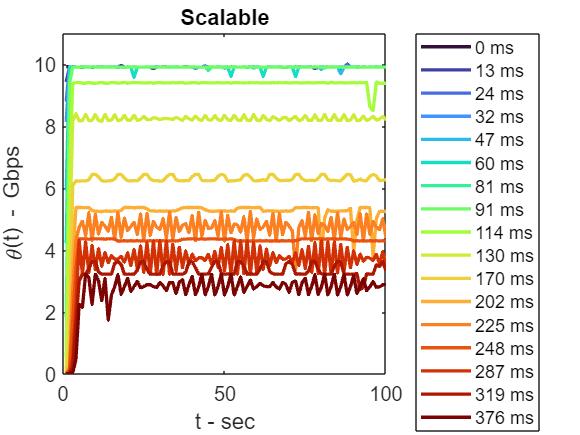

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-scalable-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_scalable_polatis_2f_time,testbed_scalable_polatis_2f_trace]=read_tracex_testbed_txt('scalable','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_scalable_polatis_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('Scalable')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

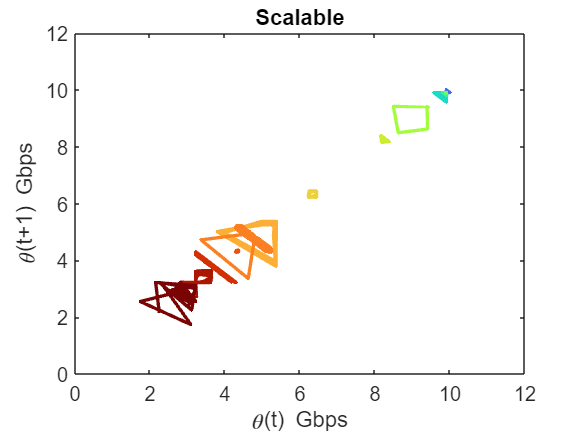


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_scalable_polatis_2f_trace(i,j+1);
    end
    plot(testbed_scalable_polatis_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('Scalable');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

### Westwood Traces

Polatis-ixia: no loss

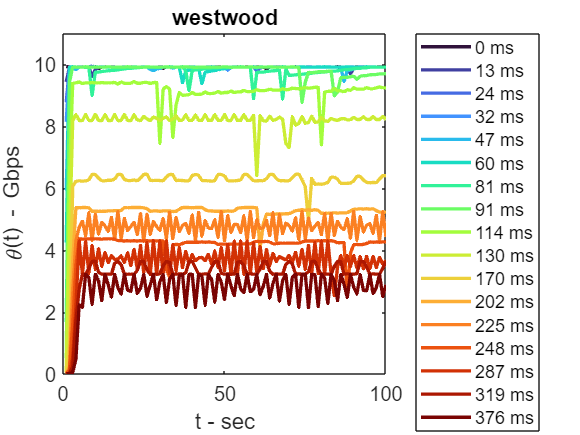

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-westwood-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_westwood_time,testbed_westwood_trace]=read_tracex_testbed_txt('westwood','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_westwood_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('westwood');
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

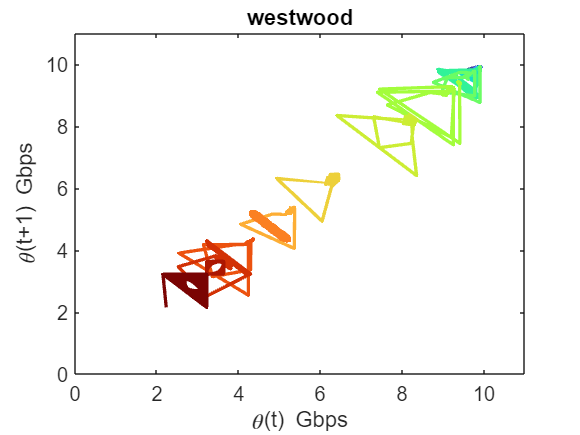


cc_turbo=turbo(num_rtt_g);
start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_westwood_trace(i,j+1);
    end
    plot(testbed_westwood_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('westwood');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 11])
ylim([0 11])

### YEAH Polatis

Polatis-ixia: no loss

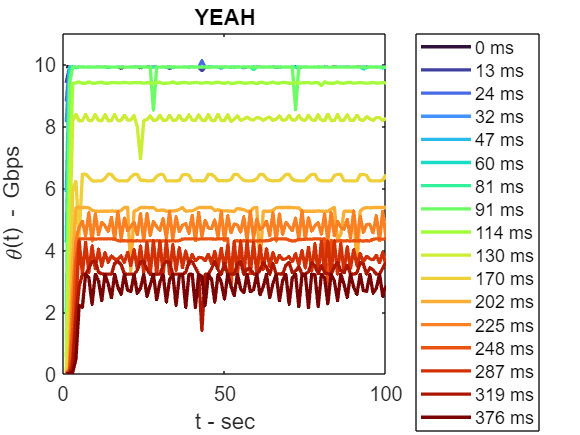

file_name='iperf_tcp_log_q1-c1-p-ixia-p-c2-q2-yeah-no-loss-2streams-trace';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_yeah_2f_time,testbed_yeah_2f_trace]=read_tracex_testbed_txt('yeah','1',rtt_g,testbed_dir_name_g);

cc_turbo=turbo(num_rtt_g);
figure(100); clf reset
for i=1:num_rtt_g
    plot(testbed_yeah_2f_trace(i,:)/1000,"Color",cc_turbo(i,:),'LineWidth',2); hold on
end
title('YEAH')
xlabel('t - sec');
ylabel('\theta(t) - Gbps','Interpreter','tex');
ylim([0 11])
legend(celldate_g,'Location','eastoutside');
set(gca,'FontSize',12);

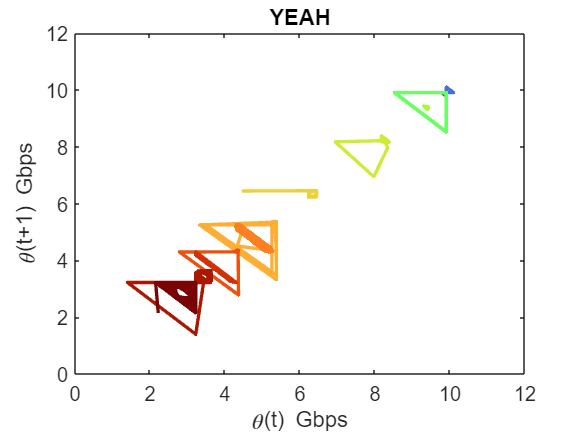


start_cc=5;
figure(201); clf reset
for i=1:num_rtt_g
    for j=1:99
        poincare(j)=testbed_yeah_2f_trace(i,j+1);
    end
    plot(testbed_yeah_2f_trace(i,start_cc:99)/1000,poincare(start_cc:99)/1000,'LineWidth',2,"Color",cc_turbo(i,:)); hold on
end
title('YEAH');
xlabel('\theta(t) Gbps','Interpreter','tex')
ylabel('\theta(t+1) Gbps','Interpreter','tex')
set(gca,'FontSize',12)
xlim([0 12])
ylim([0 12])

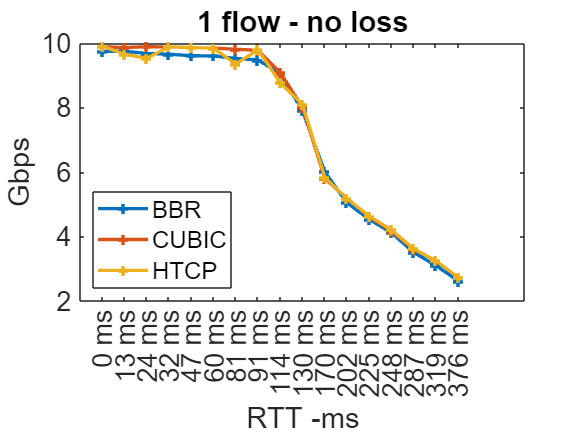


figure(101); clf reset
plot(compute_profile(testbed_bbr_polatis_2f_trace,num_rtt_g)/1000,'+-','LineWidth',2); hold on
plot(compute_profile(testbed_cubic_polatis_2f_trace,num_rtt_g)/1000,'+-','LineWidth',2); hold on
plot(compute_profile(testbed_htcp_polatis_2f_trace,num_rtt_g)/1000,'+-','LineWidth',2); hold on
set(gca,'XTick',1:length(celldate_g),'XTickLabel',celldate_g);
ylabel('Gbps');
xlabel('RTT -ms');
set(gca,'FontSize',16);
legend('BBR','CUBIC','HTCP','location','southwest');
title('1 flow - no loss')

### Functions

function profile=compute_profile(mea_arr,num_rtt)
    for ii=1:num_rtt
        profile(ii)=mean(mea_arr(ii,:));
    end
end


function [time_stream,thru_stream]=read_trace_testbed_txt(proto,rtt,dir)
    for i=1:length(rtt)
        data_file=strcat(proto,'_',int2str(rtt(i)),'ms_trace.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2]=textread(input_file,'%f %f');
            
        time_stream(i,:)=bin1;
        thru_stream(i,:)=bin2;
       
    
    end
end

function [time_stream,thru_stream]=read_tracex_testbed_txt(proto,ind,rtt,dir)
    for i=1:length(rtt)
        data_file=strcat(proto,'_',int2str(rtt(i)),'ms_trace_',ind,'.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2]=textread(input_file,'%f %f');
            
        time_stream(i,:)=bin1;
        thru_stream(i,:)=bin2;
       
    
    end
end

function [time_stream,thru_stream]=read_tracex_testbed_hybla_txt(proto,ind,rtt,dir)
    for i=1:length(rtt)
        data_file=strcat(proto,'_',int2str(rtt(i)),'ms_trace_',ind,'.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2]=textread(input_file,'%f %f');
            
        time_stream(i,:)=bin1;
        thru_stream(i,:)=bin2;
       
    
    end
end

function [time_stream,thru_stream]=read_trace_testbed(proto,rtt,dir)
    for i=1:length(rtt)
        data_file=strcat(proto,'_',int2str(rtt(i)),'ms_trace');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2]=textread(input_file,'%f %f');
            
        time_stream(i,:)=bin1;
        thru_stream(i,:)=bin2;
       
    
    end
end


Compute two coefficients

theta: throughput

tau: rtt 

num_t: number of rtts

function [theta_uc, theta_ucv]=compute_coefficient(theta,tau,num_t)
theta_int=trapz(tau(1:num_t)/max(tau(1:num_t)),theta(1:num_t)/max(theta(1:num_t)));
theta_mid=(theta(1)+theta(num_t))/(2*max(theta(1:num_t)));
theta_uc=theta_int-theta_mid/2+0.25;

theta_v=0;
for ii=1:num_t-1
    theta_v=theta_v+abs(theta(ii+1)-theta(ii));
end
theta_v;

theta_v=(num_t)*(max(theta(1:num_t))-min(theta(1:num_t)))/((num_t-1)*theta_v)-1/(num_t-1);
theta_ucv=(2*theta_uc+theta_v)/3;
end
